# MNIST con una red convolucional

En este script vamos a resolver el problema de determinar dígitos escritos a mano con una red convolucional.

addpath(genpath('examples'));
SEED = 12345;
rng(SEED);

## Carga del conjunto de datos

dir = 'examples/data/mnist/';

trainFilename = [dir 'mnist_train.gz'];
trainLabelsFilename = [dir 'mnist_train_labels.gz'];
testFilename = [dir 'mnist_test.gz'];
testLabelsFilename = [dir 'mnist_test_labels.gz'];

XTrain = processImagesMNIST(trainFilename);


Read MNIST image data...
Number of images in the dataset:  60000 ...


YTrain = processLabelsMNIST(trainLabelsFilename);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


XTest = processImagesMNIST(testFilename);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest = processLabelsMNIST(testLabelsFilename);


Read MNIST label data...
Number of labels in the dataset:  10000 ...



XTrain = extractdata(XTrain);
XTest = extractdata(XTest);

## Subivisión del conjunto de entrenamiento para validación

[trainInd, valInd, ~] = dividerand(length(XTrain), .9, .1, .0);

XVal = XTrain(:, :, :, valInd);
YVal = YTrain(valInd);
XTrain = XTrain(:, :, :, trainInd);
YTrain = YTrain(trainInd);

## Creación de la red

inputSize = [28 28];

layers = [
    imageInputLayer([inputSize 1], 'Name', 'input')
    
    convolution2dLayer([3 3], 16, 'Padding', 'same', 'Name', 'conv-1')
    reluLayer('Name', 'relu-1')
    maxPooling2dLayer([2 2], 'Stride', [2 2], 'Name', 'max-pool-1')
    
    convolution2dLayer([3 3], 32, 'Padding', 'same', 'Name', 'conv-2')
    reluLayer('Name', 'relu-2')
    maxPooling2dLayer([2 2], 'Stride', [2 2], 'Name', 'max-pool-2')
    
    convolution2dLayer([3 3], 64, 'Padding', 'same', 'Name', 'conv-3')
    reluLayer('Name', 'relu-3')
    maxPooling2dLayer([2 2], 'Stride', [2 2], 'Name', 'max-pool-3')
    
    fullyConnectedLayer(10, 'Name', 'head')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

## Opciones de entrenamiento

miniBatchSize = 16;

options = trainingOptions('sgdm', ...
    'MiniBatchSize', miniBatchSize, ...
    'MaxEpochs', 4, ...
    'InitialLearnRate', .01, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal, YVal}, ...
    'ValidationFrequency', miniBatchSize * 8, ...
    'Verbose', false, ...
    'Plots', 'training-progress' ...
);

## Entrenamiento

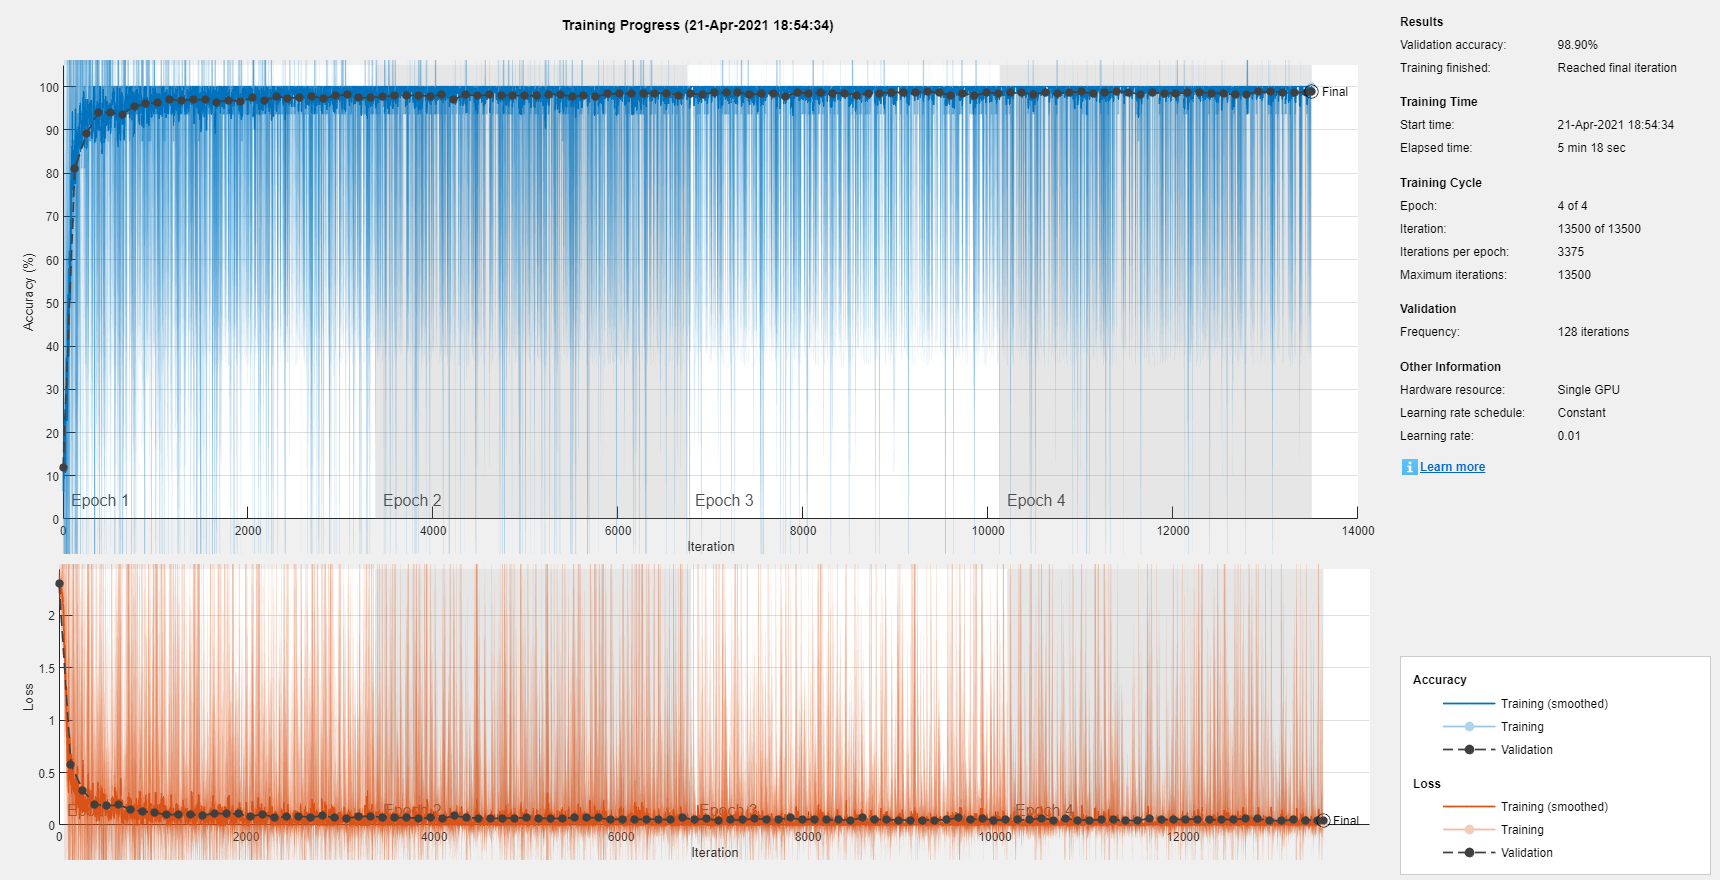

[net, info] = trainNetwork(XTrain, YTrain, layers, options);

save('examples/models/mnistCNN.mat', 'net');
save('examples/models/mnistCNNInfo.mat', 'info');

## Evaluación

cs = net.Layers(end).Classes;

probs = predict(net, XTest);
[~, YPred] = max(probs, [], 2);
YPred = cs(YPred);
acc = sum(YPred == YTest) / length(YTest);

fprintf("****************\n");

****************


fprintf("Accuracy: %0.4f\n", acc);

Accuracy: 0.9887


fprintf("****************\n");

****************


## Resultados

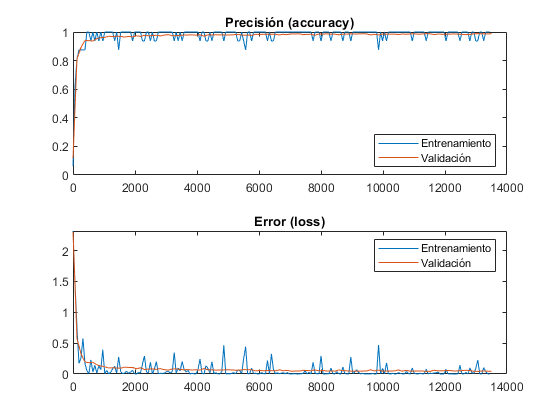

plotTraining(info, miniBatchSize * 4);

## Ejemplos

rng(SEED);

examples = zeros(28, 28, 10);
exProbs = zeros(10, 1);
exPred = zeros(10, 1);
for i = 1:10
    indices = YTest == cs(i);
    filtered = XTest(:, :, indices);
    index = floor(rand * size(filtered, 3)) + 1;
    examples(:, :, i) = filtered(:, :, index);
    
    filtered = YPred(indices);
    exPred(i) = filtered(index);
    
    filtered = probs(indices, :);
    exProbs(i) = filtered(index, exPred(i));
end

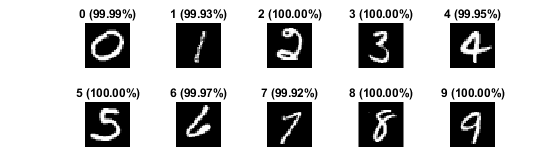

figure
position = get(gcf, 'Position');
set(gcf, 'Position',  [position(1:3) 28*6]);
for i = 1:10
    subplot(2, 5, i);
    imshow(examples(:, :, i));
    title(strcat(string(cs(exPred(i))), ...
        sprintf(' (%0.2f%%)', exProbs(i) * 100)));
end